# Aliasing 2

Matlab file used for class demo conducted during session on sampling A short recorded sample is effectively sampled at four different rates and played back. Lowpass 'antialias' filtering is done prior to decimation to avert aliasing.

Adapted for EG-247 Signals and Systems by Dr Chris P. Jobling from an example by Prof. Charles A. Bouman, School of Electrical and Computer Engineering, Purdue University, West Lafayette.

Original file: [https://engineering.purdue.edu/VISE/ee438/demos/](https://engineering.purdue.edu/VISE/ee438/demos/)

clf
set(0,'defaultaxesfontsize',16);

audioFile = 'eg-247-message.wav';
[data,Fs] = audioread(audioFile);

Plot data to cut off silence

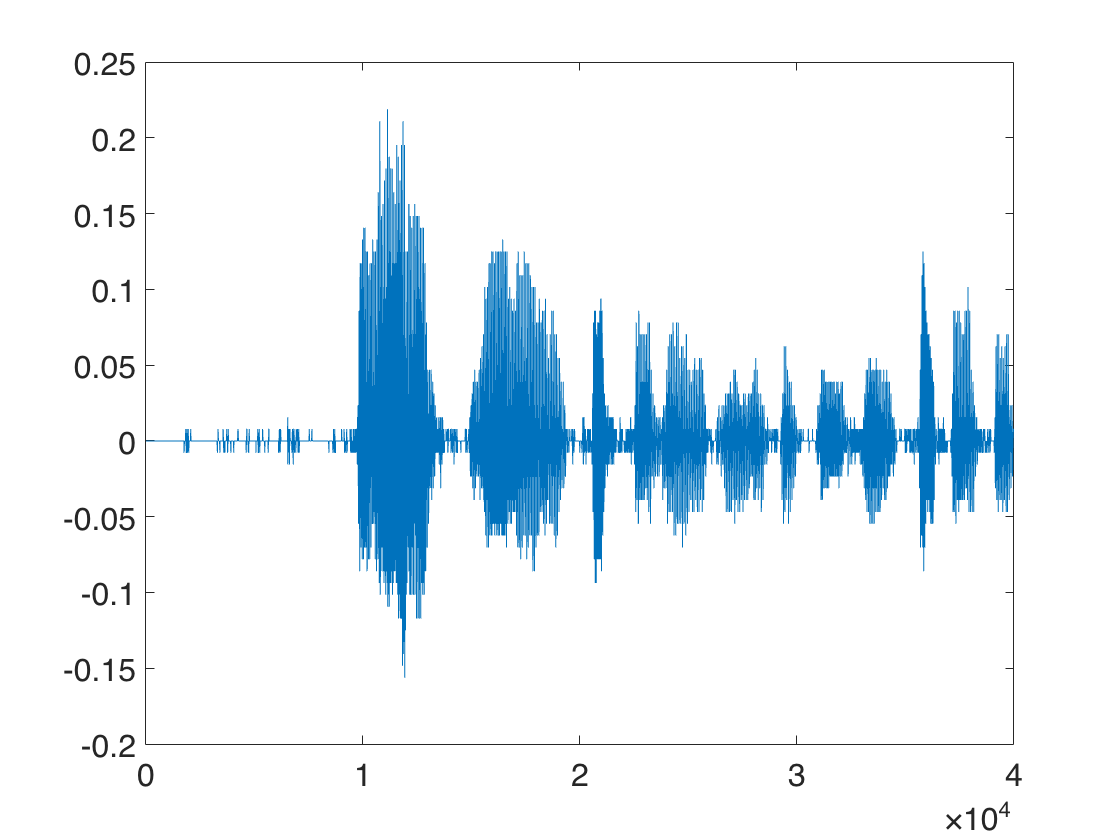

plot(data)

end1=5000;
end2=40000;
datar=data(end1:end2);
dsize=length(datar);

Compute 8192 point FFT to view spectrum of speech signal

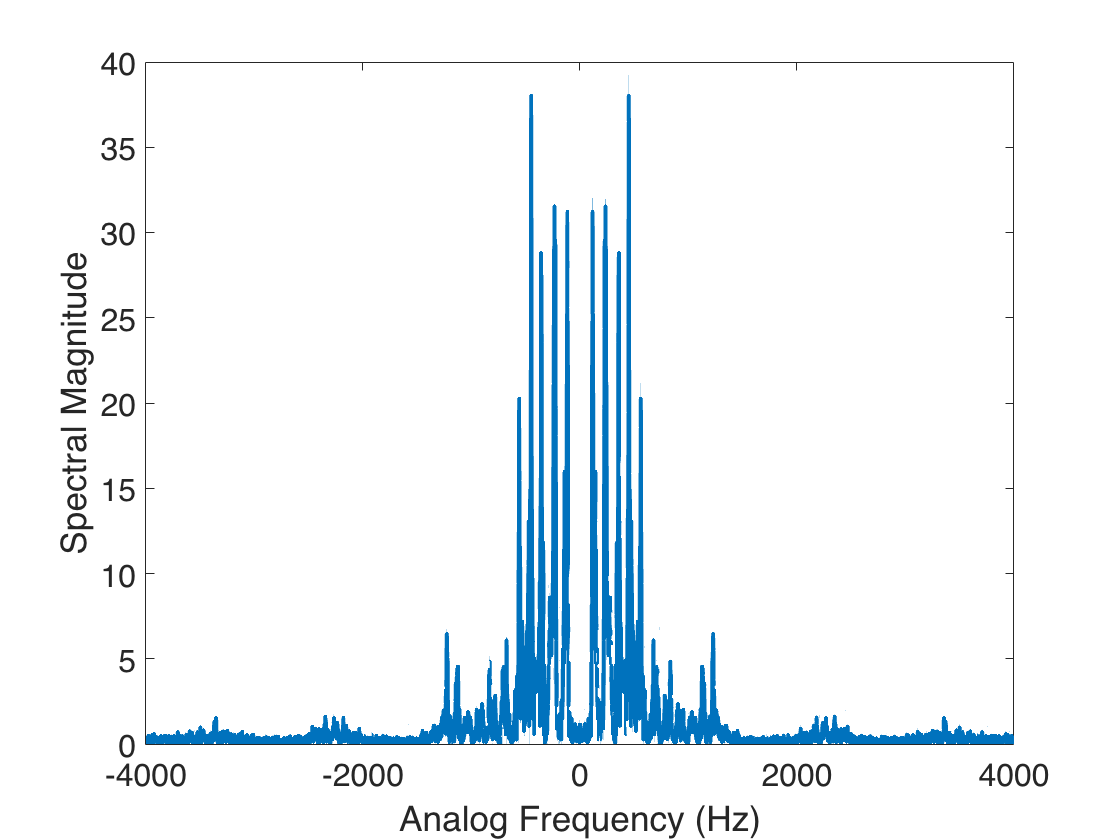

deltaf=Fs/8192;
freq=-Fs/2:deltaf:Fs/2-deltaf;
plot(freq,abs(fftshift(fft(datar,8192))),'linewidth',2)
xlabel('Analog Frequency (Hz)')
ylabel('Spectral Magnitude')

domega=2*pi/8192;
omega=-pi:domega:pi-domega;

Playback speech at original rate of 8192 Hz.

soundsc(datar,Fs)

Reduce sampling rate by a factor of 2 thru decimation and playback speech at 4096 KHz.

datar2=resample(datar,1,2);
soundsc(datar2,Fs/2)

Reduce sampling rate by a factor of 3 thru decimation and playback speech at 2731 KHz.

datar3=resample(datar,1,3);
soundsc(datar3,Fs/3)

Reduce sampling rate by a factor of 4 thru decimation and playback speech at 2048 KHz.

datar4=resample(datar,1,4);
soundsc(datar4,Fs/4)

Compute via the FFT the DTFT of each of the four sampled versions of the original speech. Plot magnitude of each DTFT over $-\pi$ to $\pi$.

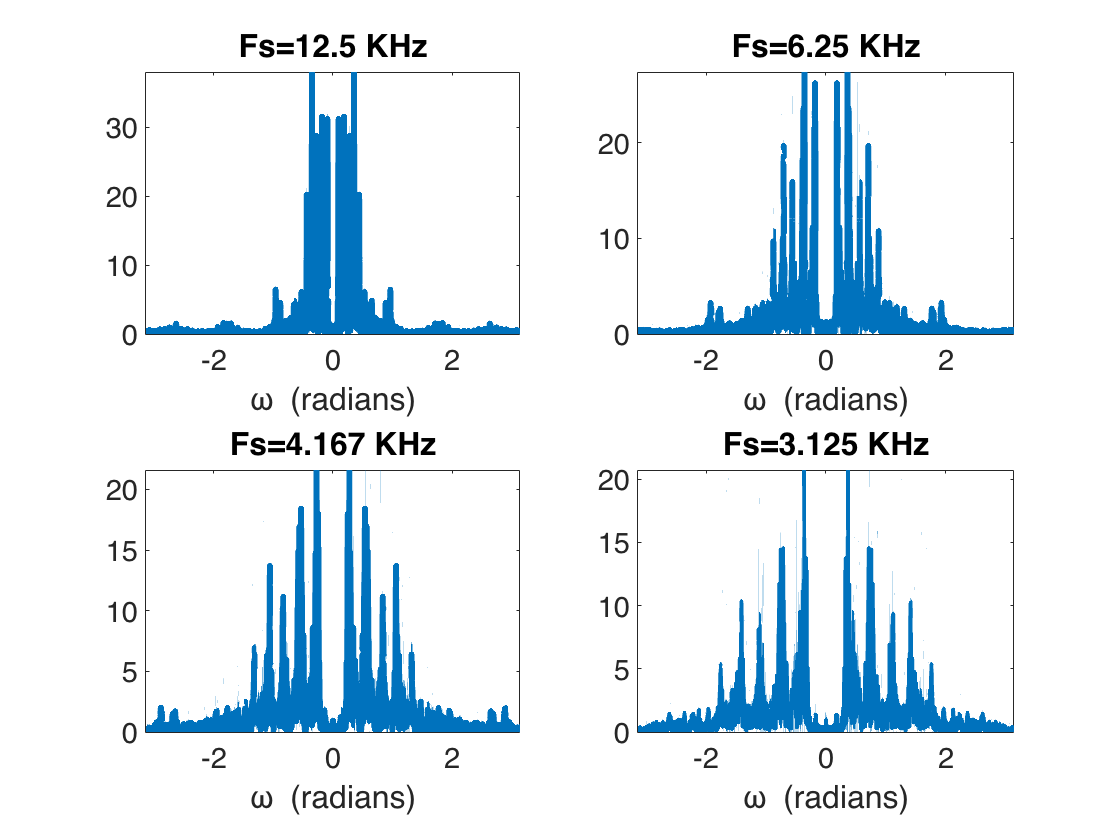

subplot(221)
dr1=abs(fftshift(fft(datar,8192)));
plot(omega,dr1,'Linewidth',3)
axis([-pi pi 0 max(dr1)])
title('Fs=12.5 KHz')
xlabel('\omega (radians)')
subplot(222)
dr2=abs(fftshift(fft(datar2,8192)));
plot(omega,dr2,'Linewidth',3)
axis([-pi pi 0 max(dr2)])
title('Fs=6.25 KHz')
xlabel('\omega (radians)')
subplot(223)
dr3=abs(fftshift(fft(datar3,8192)));
plot(omega,dr3,'Linewidth',3)
axis([-pi pi 0 max(dr3)])
title('Fs=4.167 KHz')
xlabel('\omega (radians)')
subplot(224)
dr4=abs(fftshift(fft(datar4,8192)));
plot(omega,dr4,'linewidth',2)
axis([-pi pi 0 max(dr4)])
title('Fs=3.125 KHz')
xlabel('\omega (radians)')